Load in data from the work space

|==========================================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  Activations |  Standardize |       Lambda | LayerWeights-| LayerBiasesI-|            LayerSizes |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              | Initializer  | nitializer   |                       |
|==========================================================================================================================================================================|
|    1 | Best   |      7.5842 |      31.579 |      7.5842 |      7.5842 |      sigmoid |        false |       9.6516 |           he |         ones |  49                   |
|    2 | Best   |      5.6938 |      151.15 |      5.6938 |       5.769 |         tanh |         true |   1.1255e-05 |           he |  

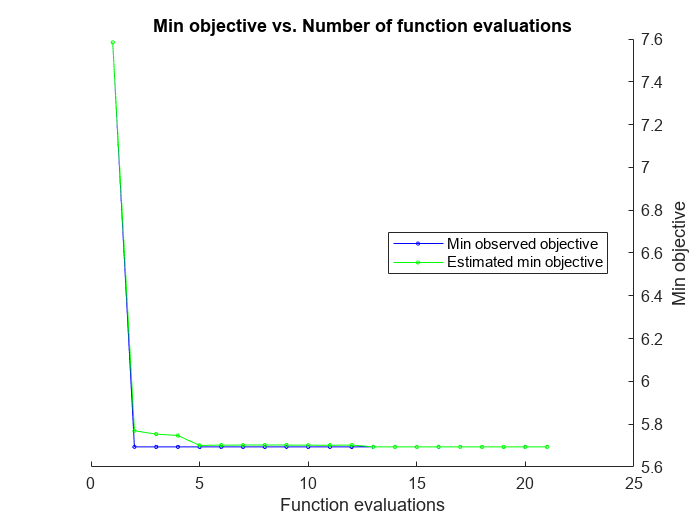

|==========================================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  Activations |  Standardize |       Lambda | LayerWeights-| LayerBiasesI-|            LayerSizes |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              | Initializer  | nitializer   |                       |
|==========================================================================================================================================================================|
|   21 | Accept |      7.2723 |      6.4177 |      5.6938 |      5.6942 |         tanh |         true |   5.4554e-08 |           he |        zeros | [  1  19]             |


 load("loadInData.mat");
data = loadInData;
electrical_load = data.AC;

% Prepare data for training
input_window_size = 168; % 7 days of hourly data
output_window_size = 24; % 1 day ahead prediction
total_window_size = input_window_size + output_window_size;

% Prepare the input and target series
n = length(electrical_load)/input_window_size;
X = [data.AC(1:end-1) data.weekDay(1:end-1)];
T = data.AC(2:end);
% 
% for i = 1:(n -  1)
%     idx=1+(i-1)*input_window_size;
%     X(:,i) =  electrical_load(idx:idx + input_window_size - 1)';
%     T(:,i) =  electrical_load(idx + input_window_size:idx + total_window_size - 1)';
% end


% Split data into training and testing sets
train_ratio = 0.7;
num_train = floor(length(X) * train_ratio);
X_train = X(1:num_train,:);
T_train = T(1:num_train);
X_test = X(num_train+1:end,:);
T_test = T(num_train+1:end);

% Create and Train Neural Network

opt = struct("ShowPlots",true,"MaxObjectiveEvaluations",50);

net = fitrnet(X_train, T_train,"OptimizeHyperparameters","all","HyperparameterOptimizationOptions", opt);

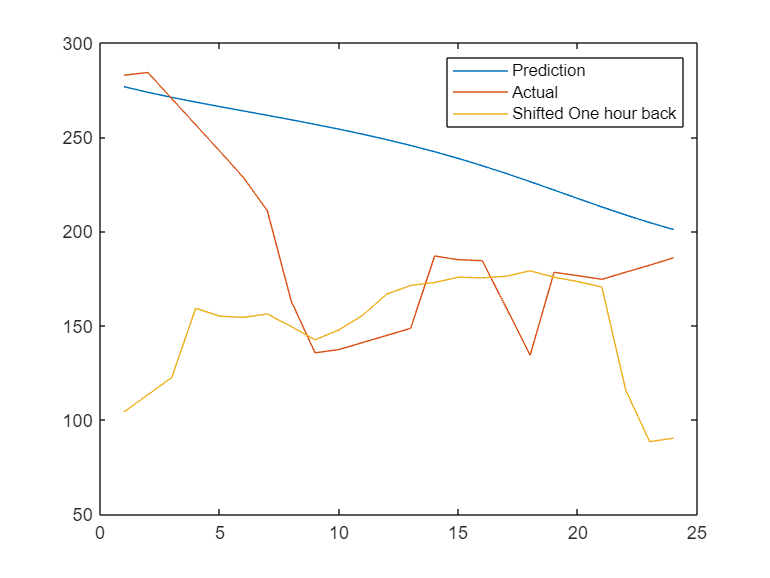


% Perform Forecast

timeStep= 1;
for j = 1:(floor(length(X_test)/timeStep)-ceil(24/timeStep)-72)
   
    offset = j*timeStep+72 ;
    
    input = X_test(1:offset); 
    first_forecast = predict(net, input);
    Yin = first_forecast(end:end);
    Y = zeros(24,1);
    Y(1) = Yin;
    
    for i=2:24
        input = [input(2:end)' Y(i-1)'];
        input = input';
        YNext = predict(net, input);
        Y(i)  = YNext(end:end);
    end
    
    Ypred{j}(:) = Y;
    Yactual{j}(:) = T_test(offset:offset+23);
end

YmapeHr = zeros(24,1);
Yrmse   = zeros(24,1);
YseCal = zeros(24,1);

for i=1:j
Ymape{i}(:) = abs(Yactual{i} - Ypred{i})./(Yactual{i})*100;
YmapeHr(:) = YmapeHr + Ymape{i}(:);

YseCal(:) = YseCal(:) + (Yactual{i}(:) - Ypred{i}(:)).^2;
end

YmapeHr = YmapeHr./j;
Yrmse = sqrt(YseCal./j);



plot(Ypred{1})
hold on
plot(Yactual{1})

hold off
legend("Prediction", "Actual")

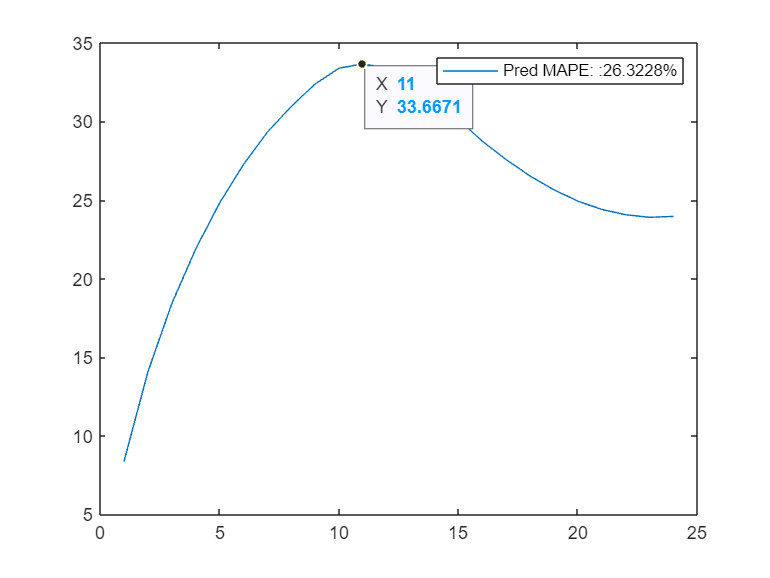



plot(YmapeHr)
legend("Pred MAPE: :" + mean(YmapeHr) +"%")

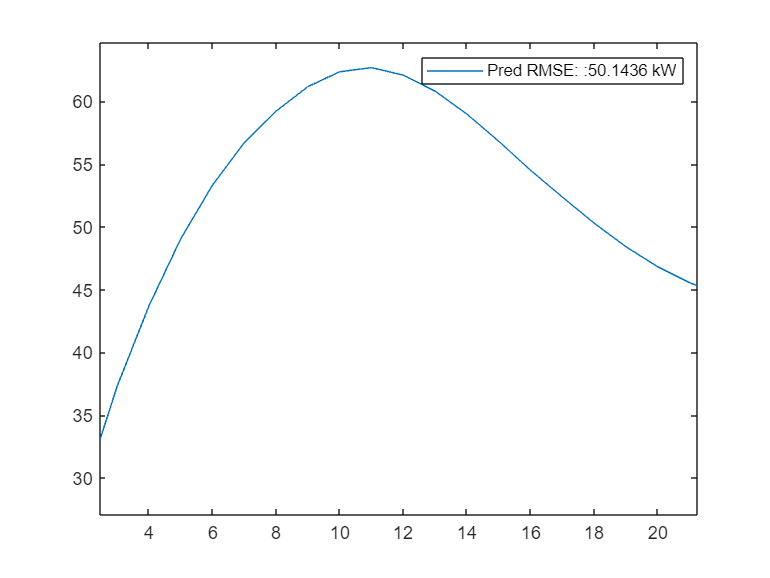


plot(Yrmse)
legend("Pred RMSE: :" + mean(Yrmse) +" kW")